# 源信号

## 载波

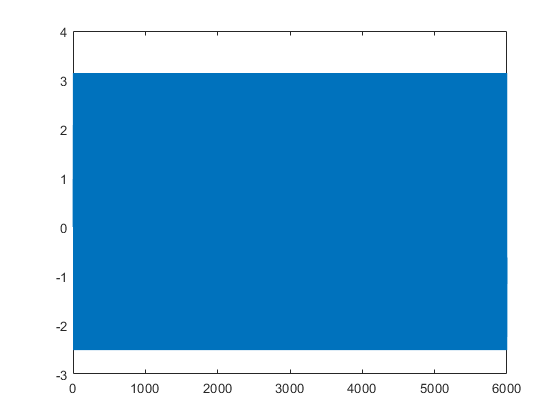

clear
f_source = 100;
A_1 = 2;
E = 0 ;
%采样点数 10s
Ns = 10; % 单个周期采样点数
fs = f_source * Ns;
N = 6 * fs;
n = 0 : N-1;
%时间序列
% global t;
t = n / fs ;

phase = linspace(0, 2 * pi, Ns + 1); % 采样相位

% y_source_i = A_1 * sin(2 * pi * f_source * t) + E;
% y_source_q = A_1 * cos(2 * pi * f_source * t) + E;
% y_source_i = A_1 * sin(2 * pi * n /10 ) + E;
% y_source_q = A_1 * cos(2 * pi * n /10 ) + E;
y_source_i = A_1 * cos(phase(mod(n, Ns)+1)) + E;
y_source_q = A_1 * sin(phase(mod(n, Ns)+1)) + E;
y_source = y_source_i + y_source_q * 1i;

y_an = angle(y_source);

% Alpha =  2 * pi * f_source * t;
% Alpha = 2 * pi *  n /10 ;
% Alpha = phase(mod(n,Ns)+1) ;
figure;
% subplot(3, 1, 1);
plot(y_an);

## 延时


A_2 = 1.5;
t_x = (n + 7) / fs ;
x_source_i = A_2 * cos(phase(mod(n, Ns)+1)) + E;
x_source_q = A_2 * sin(phase(mod(n, Ns)+1)) + E;
x_source = x_source_i + x_source_q * 1i;
x_an = angle(x_source);
figure;
plot(x_an);

## tag

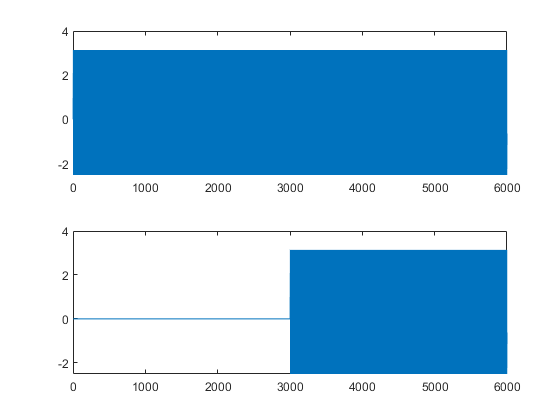



x_s = [zeros(1, length(x_source)/2) x_source(1, 1 + length(x_source)/2 : end) ];
x_s_an = angle(x_s);

figure
subplot(2,1,1);
plot(x_an);
subplot(2,1,2);
plot(x_s_an);

## 加和


x_y = y_source + x_s;
xy_an = angle(x_y);

figure
plot(xy_an);

## 取点


po = 3002;
theta_1 = y_an(1, po)

theta_1 = 0.6283

theta_2 = x_s_an(1, po)

theta_2 = 0.6283

theta_3 = xy_an(1, po)

theta_3 = 0.6283

sin_2 = sin(theta_2)

sin_2 = 0.5878


v_1 = y_source(1, po)

v_1 = 1.6180 + 1.1756i

v_2 = x_s(1, po)

v_2 = 1.2135 + 0.8817i

v_3 = x_y(1, po)

v_3 = 2.8316 + 2.0572i



B_1 = 1/tan(theta_3);
B_2 = A_1 * (sin(theta_1) - tan(theta_3) * cos(theta_1)) / (A_2 * tan(theta_3));

syms x
f=(B_1 ^ 2 + 1) *  x^2 + 2 * B_1 * B_2 * x + B_2 ^ 2 - 1

$$f = \frac{814708826177391\,x^{2}}{281474976710656}+\frac{1421956931911293\,x}{2535301200456458802993406410752}-\frac{182687704666362864775460604089527793686688040977}{182687704666362864775460604089535377456991567872}$$

result=solve(f==0,x)

$$result = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{16537476158419373985520337479157529292436630188622287702312745}}{9784326309301206145857535082496}-\frac{473985643970431}{4892163154650603072928767541248}\\ \frac{\sqrt{2}\,\sqrt{16537476158419373985520337479157529292436630188622287702312745}}{9784326309301206145857535082496}-\frac{473985643970431}{4892163154650603072928767541248} \end{array}\right)$$


sin_theta = double(result)

sin_theta =    -0.5878
    0.5878


arsin = double(asin(result))

arsin =    -0.6283
    0.6283


po = 3003;
theta_1 = y_an(1, po)

theta_1 = 1.2566

theta_2 = x_s_an(1, po)

theta_2 = 1.2566

theta_3 = xy_an(1, po)

theta_3 = 1.2566

sin_2 = sin(theta_2)

sin_2 = 0.9511


v_1 = y_source(1, po)

v_1 = 0.6180 + 1.9021i

v_2 = x_s(1, po)

v_2 = 0.4635 + 1.4266i

v_3 = x_y(1, po)

v_3 = 1.0816 + 3.3287i



B_1 = 1/tan(theta_3);
B_2 = A_1 * (sin(theta_1) - tan(theta_3) * cos(theta_1)) / (A_2 * tan(theta_3));

syms x
f=(B_1 ^ 2 + 1) *  x^2 + 2 * B_1 * B_2 * x + B_2 ^ 2 - 1

$$f = \frac{1244764322660933\,x^{2}}{1125899906842624}+\frac{2535774204123923\,x}{81129638414606681695789005144064}-\frac{2923003274661805836407369665432559277247320755491}{2923003274661805836407369665432566039311865085952}$$

result=solve(f==0,x)

$$result = \left(\begin{array}{c} -\frac{\sqrt{29107601530560734756666509874158074754558085878828596107868374753}}{179389444470395702680338433048576}-\frac{2535774204123923}{179389444470395702680338433048576}\\ \frac{\sqrt{29107601530560734756666509874158074754558085878828596107868374753}}{179389444470395702680338433048576}-\frac{2535774204123923}{179389444470395702680338433048576} \end{array}\right)$$


sin_theta = double(result)

sin_theta =    -0.9511
    0.9511


arsin = double(asin(result))

arsin =    -1.2566
    1.2566


po = 3004;
theta_1 = y_an(1, po)

theta_1 = 1.8850

theta_2 = x_s_an(1, po)

theta_2 = 1.8850

theta_3 = xy_an(1, po)

theta_3 = 1.8850

sin_2 = sin(theta_2)

sin_2 = 0.9511


v_1 = y_source(1, po)

v_1 = -0.6180 + 1.9021i

v_2 = x_s(1, po)

v_2 = -0.4635 + 1.4266i

v_3 = x_y(1, po)

v_3 = -1.0816 + 3.3287i



B_1 = 1/tan(theta_3);
B_2 = A_1 * (sin(theta_1) - tan(theta_3) * cos(theta_1)) / (A_2 * tan(theta_3));

syms x
f=(B_1 ^ 2 + 1) *  x^2 + 2 * B_1 * B_2 * x + B_2 ^ 2 - 1

$$f = \frac{1244764322660933\,x^{2}}{1125899906842624}-1$$

result=solve(f==0,x)

$$result = \left(\begin{array}{c} -\frac{33554432\,\sqrt{1244764322660933}}{1244764322660933}\\ \frac{33554432\,\sqrt{1244764322660933}}{1244764322660933} \end{array}\right)$$


sin_theta = double(result)

sin_theta =    -0.9511
    0.9511


arsin = double(asin(result))

arsin =    -1.2566
    1.2566
